# Proyecto Final De Ciencia De Los Datos

## Universidad Autónoma del Estado de México

## CU UAEM Zumpango

## Ingeniería en Computación

## Ciencia de los Datos

## Integrantes: 

Fernando Emanuel Santacruz Lara

Kevin Omar Lazaro Ortega

Isaac Antonio Maldonado

## Profesor: Asdrúbal López Chau

## Noviembre 2022

## Conjunto de datos

Los datos analizados en está ocasión son precios historicos de las acciones de varias empresas que se desarrollan en el ambito tecnologico, las cuales son Amazon, Apple, Intel, NVidia, Google, Uber, Facebook, Netflix y Tesla. Estos conjuntos de datos consisten en describir los precios de las acciones de las empresas, empezando algunas en los año 1980 hasta Marzo de 2022. Los campos considerados dentro de los datos son Date(Fecha), Open(Precio de apertura), Close(Precio de cierre), Adj Close(Precio de cierre ajustado), High(Precio más alto), Low(Precio más bajo) y Volume(Promedio de ventas de la acción).

## Preguntas

¿Conviene invertir en acciones después de la pandemia?

Los estragos de la pandemia se viven actualmente en cualquier ambito, por lo que preguntarse si vale la pena invertir en alguna de las empresas mencionadas es algo a lo que se busca dar una solución o un acercamiento a la respuesta, por lo que se plantea la pregunta anterior. Se busca dar solución con regresión lineal, con la cual podemos formular la hipotesis de si "El volumen de ventas de acciones, depende de el precio de cierre ajustado, a lo largo de los 3 años analizado"

¿Cómo afecto la Pandemia anualmente a la venta de acciones?

Saber que paso con las acciones de las empresas ante una crisis como lo fue la pandemia, es algo que nos resulya util para responder la pregunta anterior y así saber cual fue la reacción del mercado financiero ante un reto nunca antes visto. Daremos solución con la grafica de los promedios por año de cada una de las empresas

¿En que año de la pandemia la venta acciones tuvieron comportamiento brusco?

El ambito financiero es un subir y bajar, las compañias enfocadas en la tecnología, poco a poco dominan el mercado, por lo que se requiere saber en que año se tuvo una repercusión positiva o negativa, la cual resalte a comparación de los demas. Usando de igual manera los promedios y sus grafos se busca interpretar en que año de pandemia se percibe alguna anormalidad

¿Qué relación se tuvo en cuanto a los precios de apertura y cierre en la pandemia?

La pregunta es util para determinar futuros comportamientos en la venta de acciones, en está ocasión, saber si existe alguna relación entre el precio ajustado de cierre y el volumen de ventas. Esta pregunta la respondemos con el coeficiente de pearson que busca tener una relación entre el aumento de los precios de cierre y apertura, los cuales son importantes para determinar el volumen de ventas

¿Cual fue el peor año de pandemia para la venta de acciones?

Saber cual fue el año con mayor caida, de esa manera se espera conocer si el mercado financiero cambio al inicio o final del rango de años que se tiene. Dando solución a esta pregunta hacemos uso del promedio de volumenes, tanto en su forma grafica como numerica.

## Preparando datos

path = "../Datasets";%Cargamos path de los archivos
%Determinamos los nombres
name = "/Google.csv";
name1 = "/APPLE.csv";
name2 = "/INTEL.csv";
%Cargamos los archivos de las empresas
file = readtable(strcat(path,name),"VariableNamingRule","preserve");
file1 = readtable(strcat(path,name1),"VariableNamingRule","preserve");
file2 = readtable(strcat(path,name2),"VariableNamingRule","preserve");
% Normalizamos datos de las fechas
d = file.Date.Year;
d1 = file1.Date.Year;
d2 = file2.Date.Year;
% Encontramos los indices de las fechas de 2019 a 2022 File0
if0 = find(d ==2019);
i2f0 = find(d== 2020);
i3f0 = find(d == 2021);
i4f0 = find(d == 2022);
%File1
if1 = find(d1 ==2019);
i2f1 = find(d1 == 2020);
i3f1 = find(d1 == 2021);
i4f1 = find(d1 == 2022);
%File2
if2 = find(d2 ==2019);
i2f2 = find(d2 == 2020);
i3f2 = find(d2 == 2021);
i4f2 = find(d2 == 2022);
%Creamos nueva tabla con años de 2019-2022 con la cual trabajaremos
ntab = file((if0(1):i4f0(end)),:); 

Index exceeds the number of array elements. Index must not exceed 0.

ntab1 = file1((if1(1):i4f1(end)),:); 
ntab2 = file2((if2(1):i4f2(end)),:); 
%Convertimos en categorical la cabecera Date(solo toma el año)
ntab.Date = categorical(ntab.Date.Year); 
ntab1.Date = categorical(ntab1.Date.Year); 
ntab2.Date = categorical(ntab2.Date.Year); 

## Analisis exploratorio

%Graficación de datos
g = parallelplot(ntab)

g =   ParallelCoordinatesPlot with properties:

            SourceTable: [814×7 table]
    CoordinateVariables: {'Date'  'Open'  'High'  'Low'  'Close'  'Adj Close'  'Volume'}
          GroupVariable: ''

  Show all properties


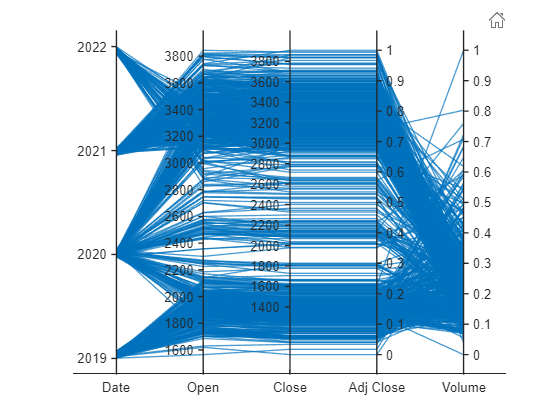

g =   ParallelCoordinatesPlot with properties:

            SourceTable: [814×7 table]
    CoordinateVariables: {'Date'  'Open'  'Close'  'Adj Close'  'Volume'}
          GroupVariable: ''

  Show all properties


g.CoordinateVariables = {'Date','Open','Close','Adj Close','Volume'}

%
g1 = parallelplot(ntab1)

g1 =   ParallelCoordinatesPlot with properties:

            SourceTable: [814×7 table]
    CoordinateVariables: {'Date'  'Open'  'High'  'Low'  'Close'  'Adj Close'  'Volume'}
          GroupVariable: ''

  Show all properties


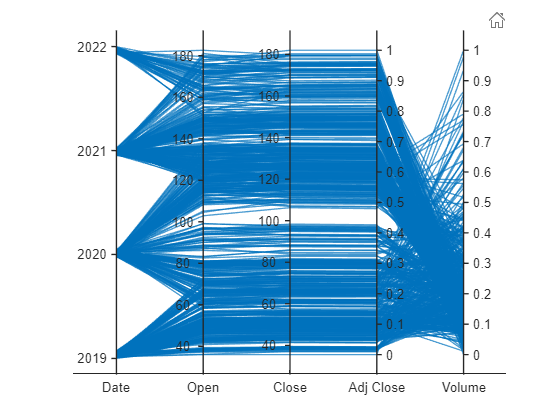

g1 =   ParallelCoordinatesPlot with properties:

            SourceTable: [814×7 table]
    CoordinateVariables: {'Date'  'Open'  'Close'  'Adj Close'  'Volume'}
          GroupVariable: ''

  Show all properties


g1.CoordinateVariables = {'Date','Open','Close','Adj Close','Volume'}

%
g2 = parallelplot(ntab2)

g2 =   ParallelCoordinatesPlot with properties:

            SourceTable: [814×7 table]
    CoordinateVariables: {'Date'  'Open'  'High'  'Low'  'Close'  'Adj Close'  'Volume'}
          GroupVariable: ''

  Show all properties


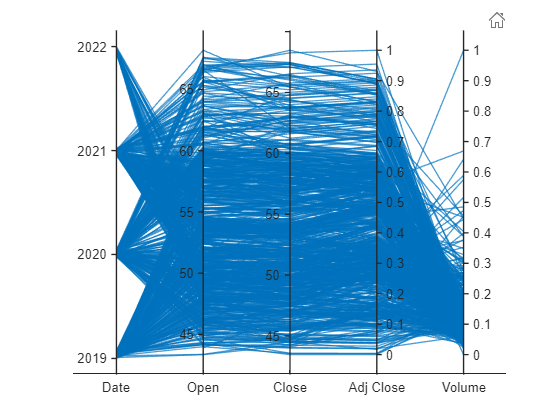

g2 =   ParallelCoordinatesPlot with properties:

            SourceTable: [814×7 table]
    CoordinateVariables: {'Date'  'Open'  'Close'  'Adj Close'  'Volume'}
          GroupVariable: ''

  Show all properties


g2.CoordinateVariables = {'Date','Open','Close','Adj Close','Volume'}

%Media, Moda y Mediana de los campos Volume
%Obtenemos nuevos indices de la nueva tabla para sumar y sacar promedios
%File0
i19 = find(ntab.Date == '2019');
i20 = find(ntab.Date == '2020');
i21 = find(ntab.Date == '2021');
i22 = find(ntab.Date == '2022');
%File1
i19f1 = find(ntab1.Date == '2019');
i20f1 = find(ntab1.Date == '2020');
i21f1 = find(ntab1.Date == '2021');
i22f1 = find(ntab1.Date == '2022');
%File2
i19f2 = find(ntab2.Date == '2019');
i20f2 = find(ntab2.Date == '2020');
i21f2 = find(ntab2.Date == '2021');
i22f2 = find(ntab2.Date == '2022');
%Obtenemos valores de cada año
v19 = ntab.Volume(i19:(i20-1));
v20 = ntab.Volume(i20:(i21-1));
v21 = ntab.Volume(i21:(i22-1));
v22 = ntab.Volume(i22:end);
%
v19f1 = ntab1.Volume(i19f1:(i20f1-1));
v20f1 = ntab1.Volume(i20f1:(i21f1-1));
v21f1 = ntab1.Volume(i21f1:(i22f1-1));
v22f1 = ntab1.Volume(i22f1:end);
%
v19f2 = ntab2.Volume(i19f2:(i20f2-1));
v20f2 = ntab2.Volume(i20f2:(i21f2-1));
v21f2 = ntab2.Volume(i21f2:(i22f2-1));
v22f2 = ntab2.Volume(i22f2:end);
%Obtenemos los promedios de cada año (2019-2022)
av19 = mean(v19);
av20 = mean(v20);
av21 = mean(v21);
av22 = mean(v22);
%
av19f1 = mean(v19f1);
av20f1 = mean(v20f1);
av21f1 = mean(v21f1);
av22f1 = mean(v22f1);
%
av19f2 = mean(v19f2);
av20f2 = mean(v20f2);
av21f2 = mean(v21f2);
av22f2 = mean(v22f2);
%Obtenemos mediana por año 2019 - 2022
med19 = median(v19);
med20 = median(v20);
med21 = median(v21);
med22 = median(v22);
%
med19f1 = median(v19f1);
med20f1 = median(v20f1);
med21f1 = median(v21f1);
med22f1 = median(v22f1);
%
med19f2 = median(v19f2);
med20f2 = median(v20f2);
med21f2 = median(v21f2);
med22f2 = median(v22f2);
%Obtenemos la moda de los años 2019 - 2022
mo19 = mode(v19);
mo20 = mode(v20);
mo21 = mode(v21);
mo22 = mode(v22);
%
mo19f1 = mean(v19f1);
mo20f1 = mean(v20f1);
mo21f1 = mean(v21f1);
mo22f1 = mean(v22f1);
%
mo19f2 = mean(v19f2);
mo20f2 = mean(v20f2);
mo21f2 = mean(v21f2);
mo22f2 = mean(v22f2);

## Análisis de los datos.

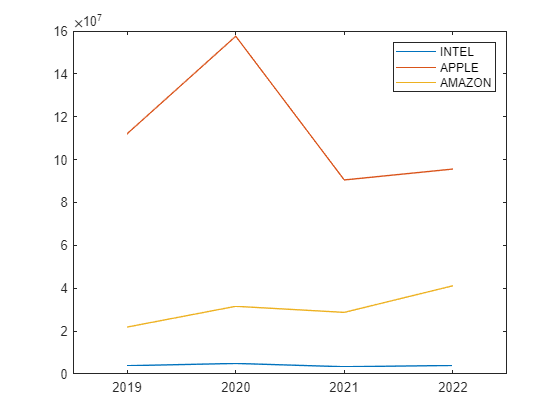

%
ye = unique(ntab.Date);
x = [av19,av20,av21,av22];
plot(ye,x)
hold on
%
x1 = [av19f1,av20f1,av21f1,av22f1];
plot(ye,x1)
hold on
%
x2 = [av19f2,av20f2,av21f2,av22f2];
plot(ye,x2)
legend("INTEL","APPLE","AMAZON")
ylim tickaligned
hold off

%Coeficiente de Pearson. Aplicado a la apertura y cierre de venta
%Con esto podemos responder a la pregunta
ap = ntab.Open;
ci = ntab.Close;
rho = corr(ap,ci,'Type','Pearson')

rho = 0.9981

%Ahora aplicaremos la regresión lineal
%Preparamos los datos a utilizar
[numTab, ~] = size(ntab);
[numTab1, ~] = size(ntab1);
[numTab2, ~] = size(ntab2);
docs = [ntab(:,(2:end)); ntab1(:,(2:end)) ; ntab2(:,(2:end))];
X = docs;
X1 = X.Volume;
Y1 = X.("Adj Close");
%[N,c] = size(X1);
%partition = cvpartition(N,"HoldOut",0.2);
%idx = training(partition);
%Xtrain = X1(idx,:);
%Ytrain = Y1(idx);
%idx = test(partition);
%Xtest = X1(idx,:);
%Ytest = Y1(idx);
fitrlinear(X1,Y1, "Learner","svm")

## Hallazgos

Al aplicar los distintos analisis a los datos se encontraron hallazgos, esperados y otros de los cuales no se buscaba una respuesta. Los hallazgos que se obtuvieron al realizar nuetro proceso fue en primer lugar una fuerte crisis de compras compulsivas de acciones, las cuales se ven reflejadas en el grafo de promedios anuales del volumen de ventas, donde en su mayoría de veces se nota un discreto o gran aumento del volumen de ventas que comprende el perido de 2019 - 2022, por lo que se interpreta como una crisis de compras compulsivas. El siguiente hallazgo es encontrado en el mismo grafo, el cual nos indica que del año 2019 - 2020 se tienen los cambios más significativos a la alza, y a la baja va del año 2020 - 2021, esto se puede interpretar como una consecuencia del fenomeno de compras compulsivas. Otro hallazgo dentro del mismo grafo es que con apenas el 22% de avance del año 2022, el volumen de ventas va a la alza, por lo que se puede interpretar que algo positivo depara el periodo 2022 - 2023.

El siguiente hallazgo se encuentra en el coeficiente de Pearson , al tener un valor cercano a 1, podemos determinar que a medida de que un valor de cierre aumenta, el de apertura aumentara, en pocas palabras existe una gran relación entre ellos. En terminos financieros podriamos interpretar este resultado como los dos elementos que más se consideran para comprar una acción.

Por ultimo podemos determinar un hallazgo, la fuerte relación que se tiene entre el precio de cierre ajustado y el volumen de ventas a lo largo de los años de pandemia, donde al tener en p un valor menor a 0.05, podemos determinar que el valor del predictor(Volume) se relaciona con la cambios en la variable de respuesta(adj close).

## Conlcusiones

Para dar conclusión al proyecto realizado, se establecen los indicadores de exito, respecto a las expectativas iniciales. Donde se puede concluir que las preguntas fueron contestadas en su mayoria de forma clara y si no fue así se dio un fuerte acercamiento a lo que sería una interpretación de expertos en el ambito financiero. Para concluir este trabajo daremos respuesta a la pregunta principal "¿Conviene invertir en acciones después de la pandemia?"; las empresas presentadas en este trabajo son enfocadas a la tecnología y podemos ver un incremento en la venta de acciones, así cómo su valor, por lo que podemos concluir que invertir en acciones después de la pandemía es seguro y conviene, siempre y cuando sea en una empresa dedicada a la tecnología, ya que la tecnología está teniendo un gran crecimiento y hay que aprovechar dicho crecimiento.